# Oscillometric model 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Arterial pulse, SBD and DBP

Column 1: ECG

Column 2: Arterial blood pressure

Column 3: Cuff pressure with the oscillometric signal

Sampling rate: 250 samples per seconds

Patient conditions: cardiomiopathy

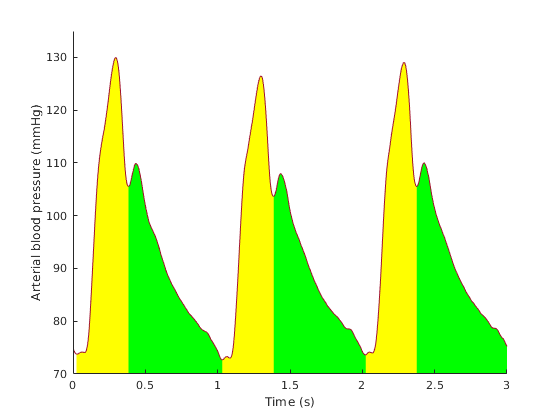

load('BP_data_250Hz.mat')
fs=250;
L=fs*3;
t=1/fs:1/fs:L/fs;
figure
axes('Layer', 'top')
hold on;
[m_sbp,i_sbp]=findpeaks(data(1:L,2),'MinPeakProminence',6,'MinPeakDistance',fs/2 );
[m_dbp_dic,i_dbp_dic]=findpeaks(-data(1:L,2),'MinPeakProminence',0.1,'MinPeakDistance',fs/5 );
hold on, area(t(i_dbp_dic(1):i_dbp_dic(2)),data(i_dbp_dic(1):i_dbp_dic(2),2),'FaceColor','y', "EdgeColor","none")
area(t(i_dbp_dic(3):i_dbp_dic(4)),data(i_dbp_dic(3):i_dbp_dic(4),2),'FaceColor','y',"EdgeColor","none")
area(t(i_dbp_dic(5):i_dbp_dic(6)),data(i_dbp_dic(5):i_dbp_dic(6),2),'FaceColor','y',"EdgeColor","none")
area(t(i_dbp_dic(2):i_dbp_dic(3)),data(i_dbp_dic(2):i_dbp_dic(3),2),'FaceColor','g',"EdgeColor","none")
area(t(i_dbp_dic(4):i_dbp_dic(5)),data(i_dbp_dic(4):i_dbp_dic(5),2),'FaceColor','g',"EdgeColor","none")
area(t(i_dbp_dic(6):L),data(i_dbp_dic(6):L,2),'FaceColor','g',"EdgeColor","none")
ylim([72,135])
plot(t,data(1:L,2))
%plot(t,70*ones(1,length(t)),'k')
xlabel('Time (s)')
ylabel('Arterial blood pressure (mmHg)')
ylim([70,135])

mean(data(1:L,2))

ans = 94.0233

## Arterial pulse over time

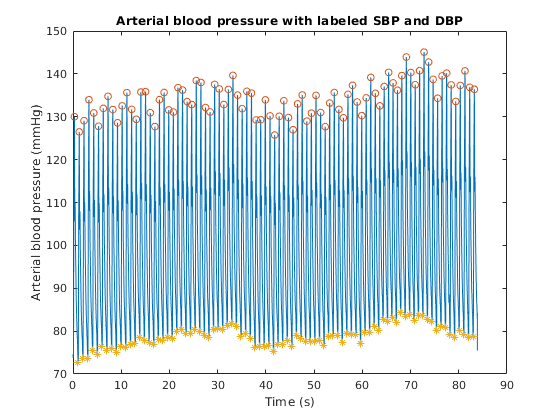

t=1/fs:1/fs:length(data)/fs;
figure
[m,i]=findpeaks(data(:,2),'MinPeakProminence',6,'MinPeakDistance',fs/2 );
plot(t,data(:,2))
hold on, plot(t(i),m,'o')
[m,i]=findpeaks(-data(:,2),'MinPeakProminence',6,'MinPeakDistance',fs/2 );
hold on, plot(t(i),-m,'*')
xlabel('Time (s)')
ylabel('Arterial blood pressure (mmHg)')
title('Arterial blood pressure with labeled SBP and DBP')

mean(data(:,2))

ans = 99.7460

## Cuff pressure

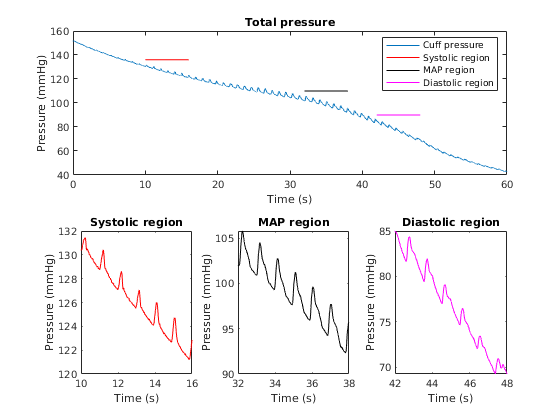

figure
time_int=[10 16; 32 38; 42 48]; % intervals for systolic, MAP and diastolic BP
t=1/fs:1/fs:length(data)/fs;
subplot (2,3,[1,3])
plot(t(1:60*fs),data(1:60*fs,3))
hold on 
plot(t(time_int(1,1)*fs:time_int(1,2)*fs),136*ones(1,6*fs+1),'r')
plot(t(time_int(2,1)*fs:time_int(2,2)*fs),110*ones(1,6*fs+1),'k')
plot(t(time_int(3,1)*fs:time_int(3,2)*fs),90*ones(1,6*fs+1),'m')
legend('Cuff pressure', 'Systolic region', 'MAP region','Diastolic region')
xlabel('Time (s)')
ylabel('Pressure (mmHg)')
title('Total pressure')
subplot (2,3,4)
plot(t(time_int(1,1)*fs:time_int(1,2)*fs),data(time_int(1,1)*fs:time_int(1,2)*fs,3),'r')
xlabel('Time (s)')
ylabel('Pressure (mmHg)')
title('Systolic region')
subplot (2,3,5)
plot(t(time_int(2,1)*fs:time_int(2,2)*fs),data(time_int(2,1)*fs:time_int(2,2)*fs,3),'k')
xlabel('Time (s)')
ylabel('Pressure (mmHg)')
title('MAP region')
subplot (2,3,6)
plot(t(time_int(3,1)*fs:time_int(3,2)*fs),data(time_int(3,1)*fs:time_int(3,2)*fs,3),'m')
xlabel('Time (s)')
ylabel('Pressure (mmHg)')
title('Diastolic region')

%Figure 6.17
% figure
% subplot 311
% if plotting ==1
% %plot(t,P) % and another way is manual integration
% xlabel("Time (s)"), ylabel("Pressure (mmHg)"), title('Arterial pressure')
% xlim([0,20])
% ylim([70,160])
% grid minor
% end
% subplot 312
% if plotting ==1
% %plot(t,omw)
% xlabel("Time (s)"), ylabel("Pressure (mmHg)")
% xlim([0,20])
% title('Total pressure')
% ylim([70,160])
% grid minor
% end
% if plotting ==1
% subplot 313
% %plot(t(peak_ind), omwe)
% xlabel("Time (s)"), ylabel("Pressure (mmHg)")
% xlim([0,20])
% ylim([-5,5])
% title('Oscillometric waveform')
% grid minor
% end

